# Lab 6: Confidence intervals

## Megan Miyasaki 

Partner: Kuan Lee

**Setup**

**First, we want to have some `background' data (presumably signal free) onto which we can inject a simulated signal. So the first step is to isolate some appropriate data from your data files. **

*Since I am working with the LHC data, below is a code that helps me build a fake poission background with a mean 100. I will use this background throught the report. *

clear;close all;clc;
size = 10000;
mean=100;
background=poissrnd(mean,[1, size]);

## Problem 1

**The first problem is to look at your background distribution and determine where the 5σ sensitivity threshold is. [Hint, you've done this several times now, look back at the first few labs.]**

*I know that 5σ is a 1 in 3.5 million change of an event happening, therefore below is the code of be find the 5σ sensitivity threshold is using matlab code. *

prob5sigma=1/3.5e6;
prob=fitdist(background','Poisson');
sigma_5=icdf(prob,1-prob5sigma);

From this code we can see that the 5σ sensitivity threshold is 54 from the mean of 100, so it is 154.

The last thing I want to do is see how this distribution looks so I will make a histogram of it below:

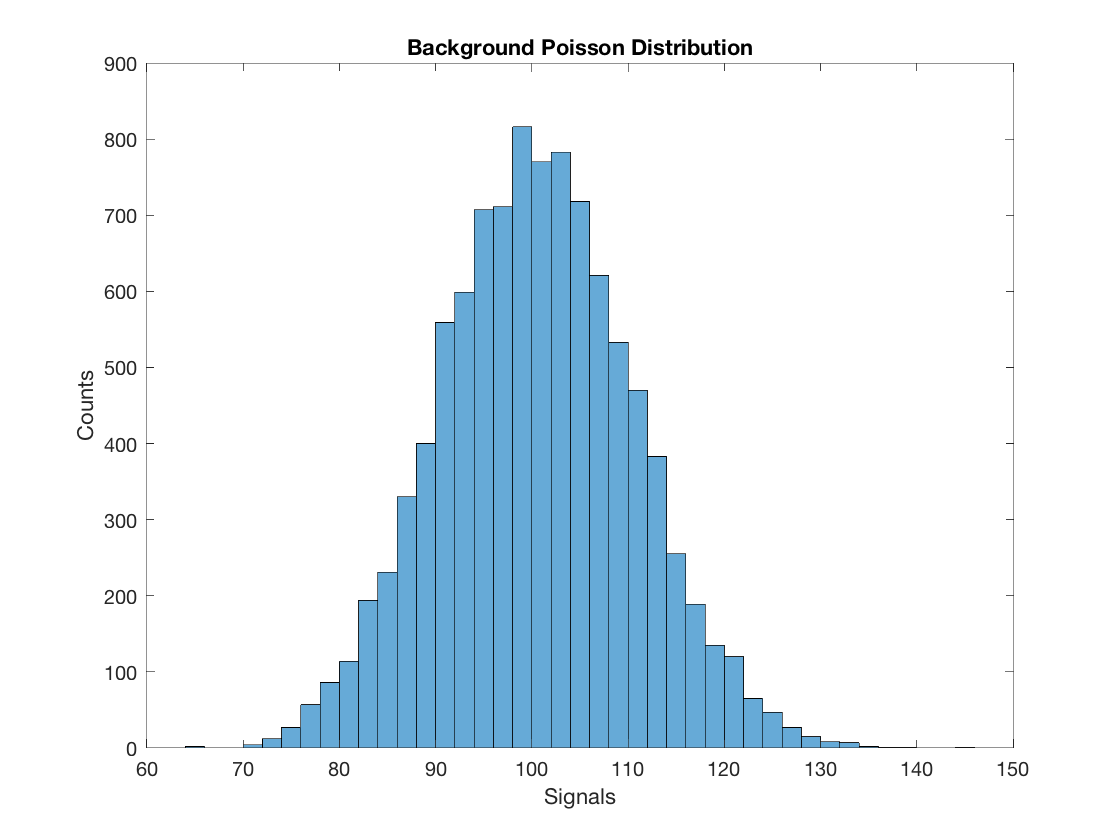

histogram(background);
title('Background Poisson Distribution')
xlabel("Signals")
ylabel("Counts")

## Problem 2

**Now create a set of injected (simulated) signals of a *****single strength*****. You will want to make your signal moderately strong, say somewhere in the 8-30σ range. Inject this signal into your background data many times.**

*I will now build injected or simulated signals of a single strength, of a 8-30σ range. *

*In order to find a 8-30σ range, we can use ****(use may be a redundent word)**** find the probability of 8*$\sigma$on a gaussian distribution then equate that to what it would be on a Poission

prob8sigma=1-normcdf(8);
prob30sigma=1-normcdf(30);
prob9sigma=1-normcdf(9);

Note how that the probability cannot be found at 9$\sigma$, therefore 30$\sigma$ would be incredible hard to find since 8$\sigma$ is already so small, therefore I will just focus for my interjected signals to be sigma to be 8$\sigma$.

sigma_8=icdf(prob,1-prob8sigma);

From here we see that 8$\sigma$ is 90 away from the mean of 100, so it is 190.

**a) Histogram how bright the observed signal appears to be, and discuss it's shape. Say in words what this histogram is telling you.**

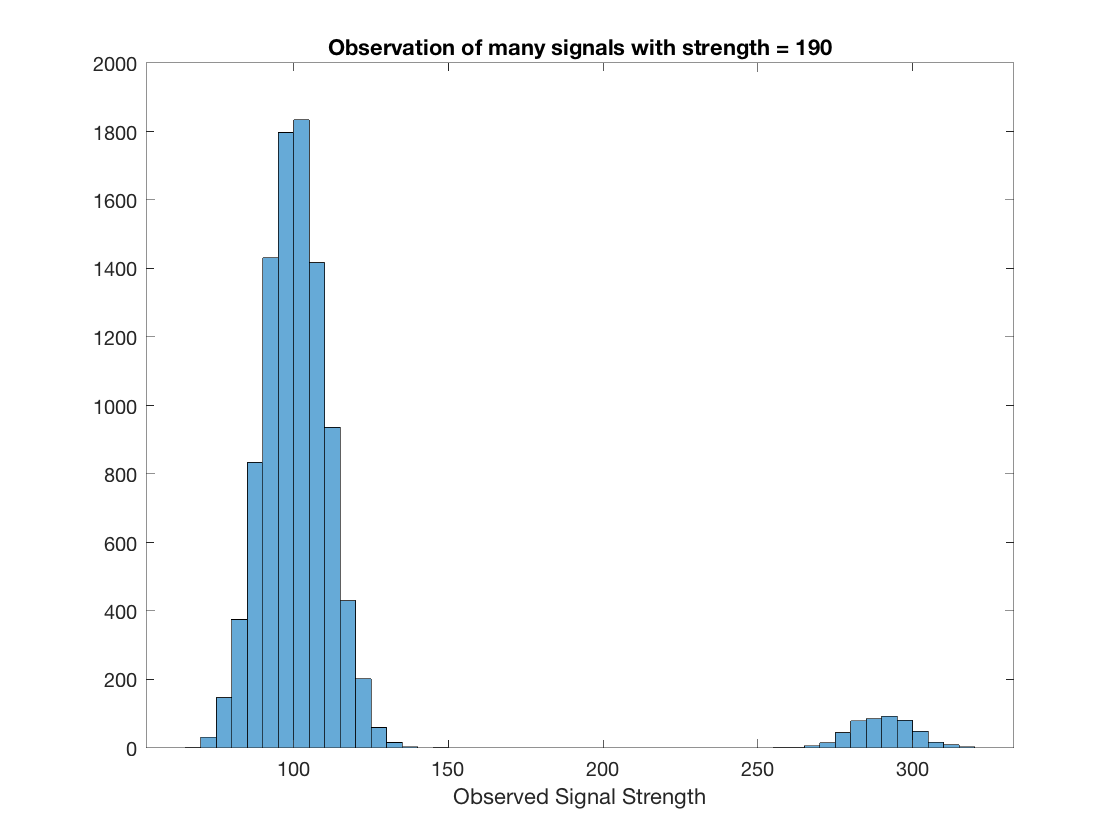

signal=zeros(1,size);
signal(randi(numel(signal),[1,500])) = 190;
obssignal=background+signal;
histogram(obssignal)
title("Observation of many signals with strength = 190")
xlabel("Observed Signal Strength")

The observed signal seems to have a small range of brighter sginals around 8$\sigma$ range, as there shoud be with our interjected data. The shape still looks Poisson distributed just less counts. 

**b) Is your observed signal biased? (e.g. is the observed value equally likely to be stronger or weaker than the true injected signal?) Is it symmetric?**

Yes, our observed signal is bias because our expected observed signa should be 190, but our distribution shows to be centered around 290. 

## Problem 3

**Now make a suite of injected signals. You will want to have a range of injected signal strengths, starting at zero and extending well above 5σ (30σ or more). **

**a) Clearly state what you are simulating, and make a 2D histogram of injected signal vs. observed signal**

*I will now make a suite of injected, as found earlier in the lab, matlab has a certain percision and we cannot calcualte higher than 8*$\sigma$ *therefore my range for the suite of injected signals will be 0 --> 500, we know 190 is 8*$\sigma$ *so 500 is many sigma away.*

probability=1-cdf('Poisson',background,210);
sigma=icdf('Normal',1-probability,0,1);


signalstrength = linspace(0,1000,size);
[scratch, signal2] = meshgrid(signalstrength);

obssignal2=background+signal2;
figure()
h=histogram2(obssignal2,signal2,100,'DisplayStyle','tile','ShowEmptyBins','on');
ylabel("Injected Signal")
xlabel("Observed Signal")
title("Confidence Intervals")

**b) If you choose the same injected signal power as in problem 2, show that you get the same answer.**

*If the signal strength equals 190, then what is that in the idex of the signal, coding that *

figure()
index=190;
signal2(index)

ans =   18.901890189018903


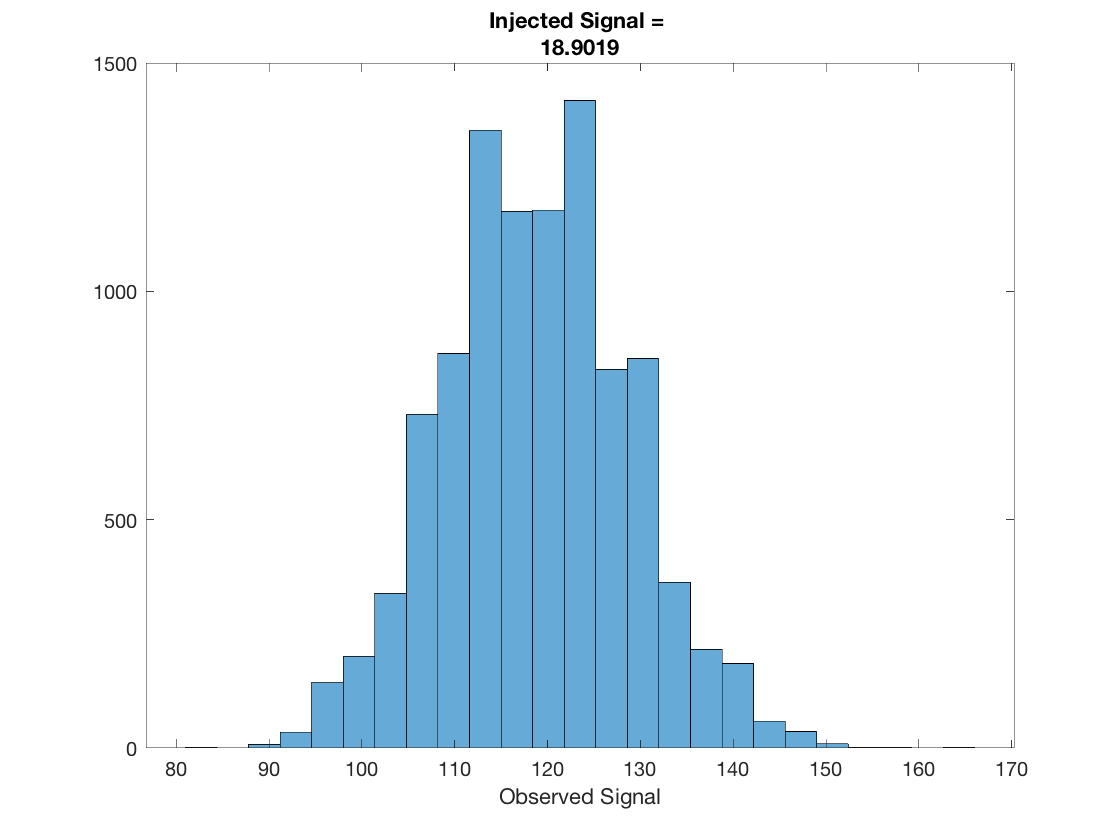

%Comment: The index 190 does not correspond to the signal strength 190. If
%you look at the matrix signal2, the signal strength 190 is at index 1901.

histogram(obssignal2(index,:),25)
title(["Injected Signal = ",num2str(signal2(index))])
xlabel("Observed Signal")

**Comment: The injected signal should be 190. Your titile says injected signal = 18.9019.**

**c) Now reverse the problem, select an observed signal (pick something quite a bit stronger than 5σ) and create a 1D histogram of the injected signal pdf(). Describe the meaning of this histogram.**

*I chose the observed signal to be 178 which is *$7\sigma$ away.

observation=178

observation =    178


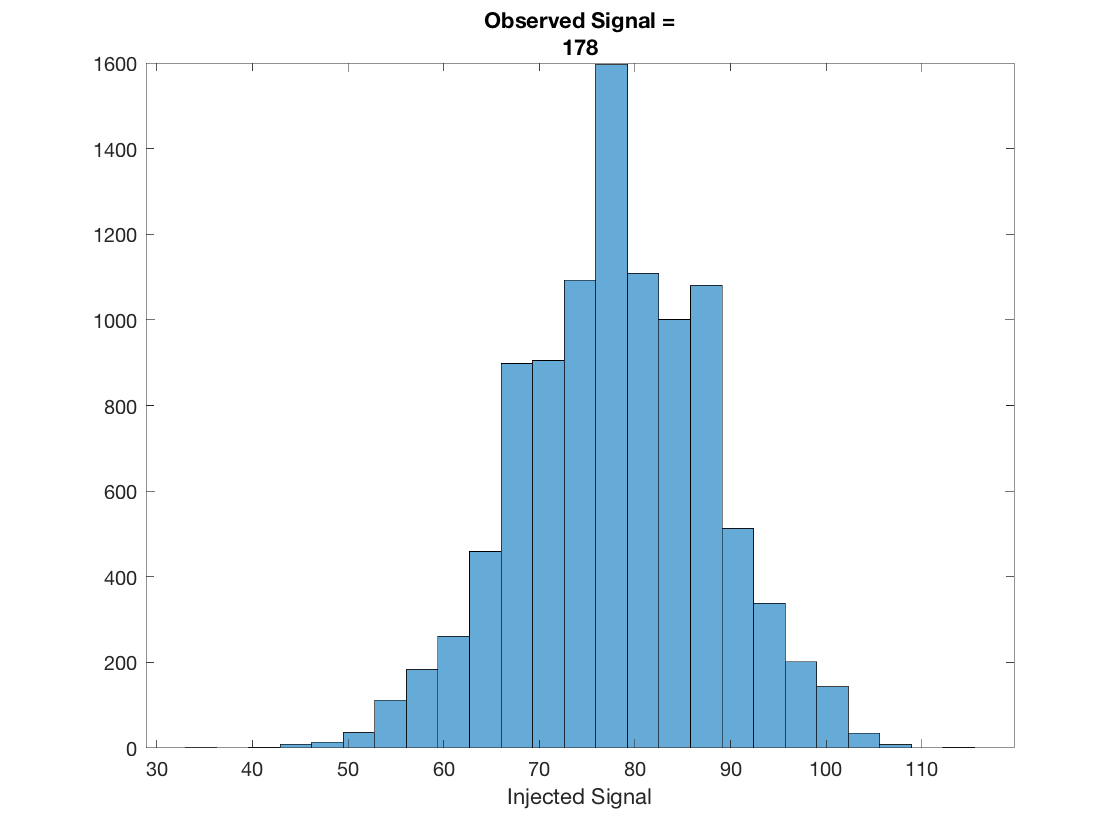

injected = signal2(abs(obssignal2-observation)<0.05);
histogram(injected,25)
title(["Observed Signal =", num2str(observation)])
xlabel("Injected Signal")

From what I see, my injected observed signal of 178 is bias, seeing as my distribution is not centered around 178 like it should be but rather 80. 

**d) For your observed signal, what is the 1σ uncertainty on the true signal strength?**

*To find this I will take the true signal strength to be 190, and find what the 1*$\sigma$*is. *

***Comment: Is 190 your observed signal?***

mean2=178;
background2=poissrnd(mean2,[1,size]);
prob2=fitdist(background2','Poisson');
prob1sigma=1-normcdf(1);
sigma_1=icdf(prob2,1-prob1sigma);
%Commment: I think you should find the distribution of the injected signal with the
%observed signal strength like you did in part c. Fit the distribution with
%Poisson and find 1 sigma uncertainty range. You can look at my lab to see
%How I found the 1 sigma uncertainty interval.

With my observed signal to be 178, the 1$\sigma$ uncertainty on the true signal strength is 192.

**e) Discuss the answer to part d in some depth. Is it symmetric? Is it biased? Does this make sense?**

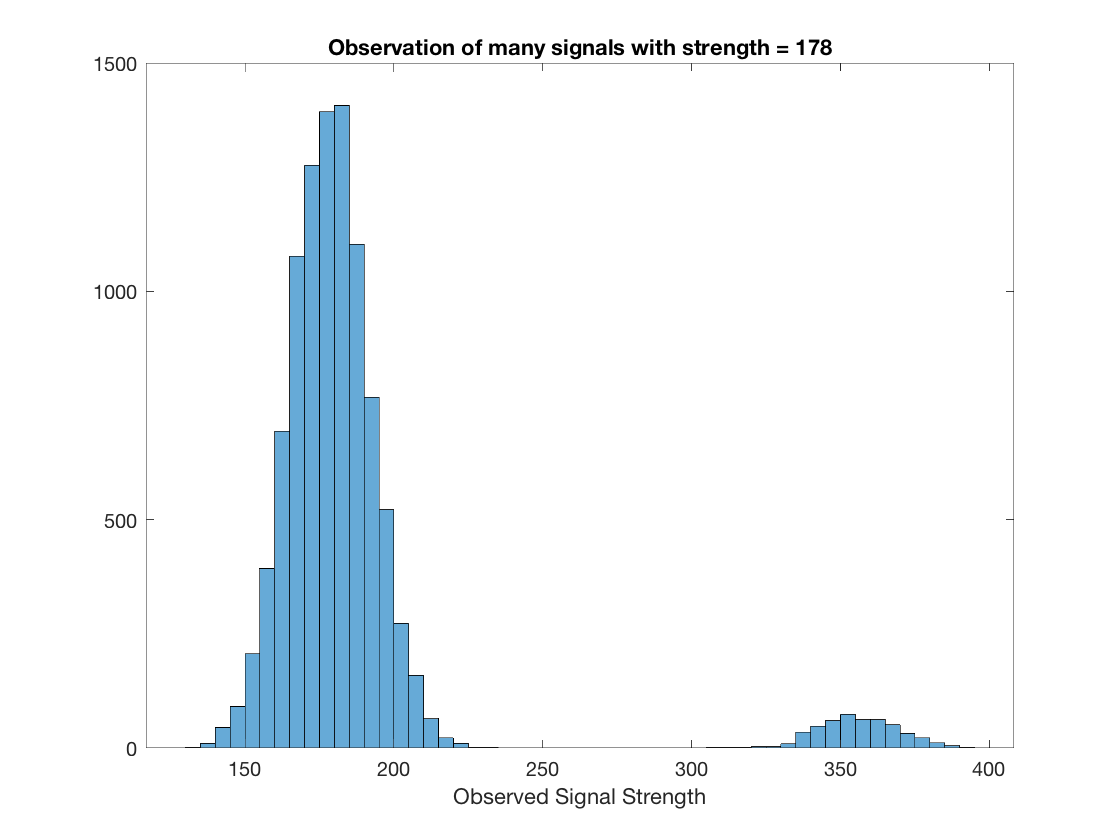

signal3=zeros(1,size);
signal3(randi(numel(signal3),[1,500])) = 178;
obssignal3=background2+signal3;
histogram(obssignal3)
title("Observation of many signals with strength = 178")
xlabel("Observed Signal Strength")

**Comment: After you find the 1 sigma uncertainty interval, you will see that it is not symmetrical. The left boundary is farther from the mean compare to the right boundary.**

It is bias because it should be centered around 178 not 275, it is also not symmetric. 

**Problem 4**

**Using the same setup as in problem 3, now pick a relatively weak signal (say in the 1σ range, exact strength not important).**

*The code below finds the 1sigma of the orginial background. *

prob1sigma_4=1-normcdf(1);
sigma_1_4=icdf(prob,1-prob1sigma_4)

sigma_1_4 =    110


1 sigma is 110, which is a relatively weak signal 

**a) Repeat problem 3c, calculating the injected signal pdf(). One of the differences you should immediately see is that the pdf() extends to zero.**

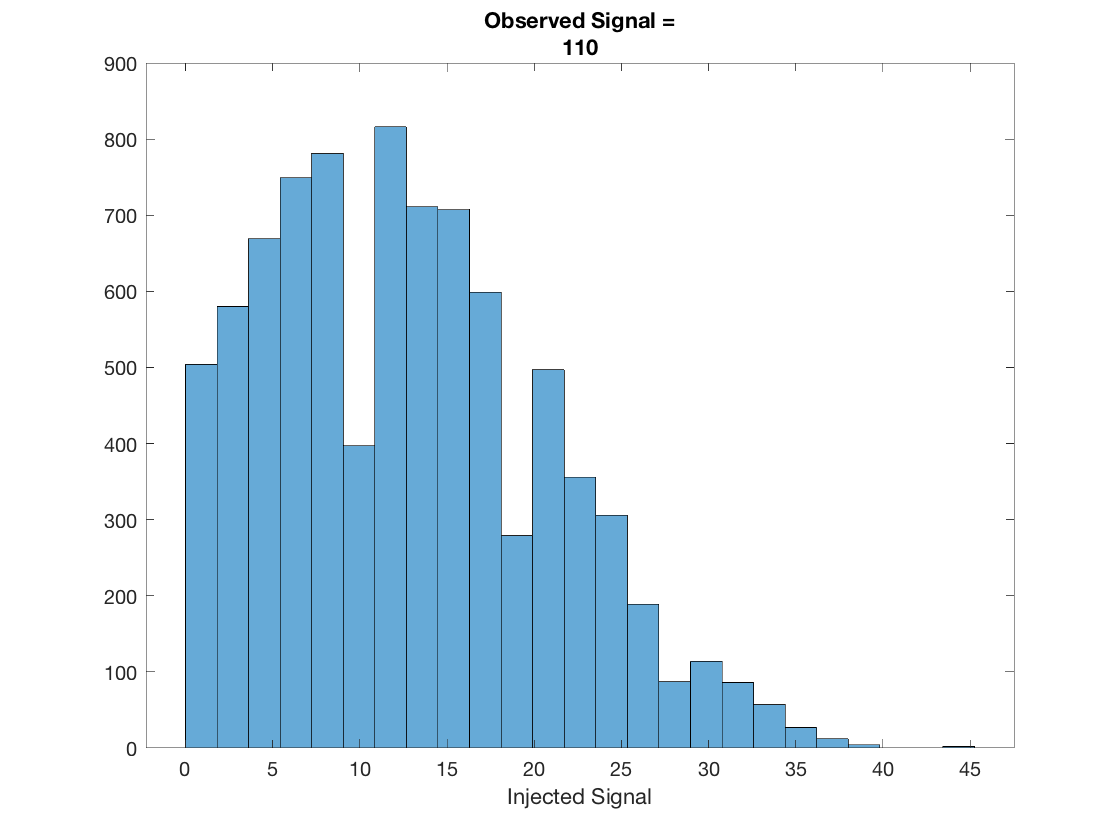

observation4=110;
injected2 = signal2(abs(obssignal2-observation4)<0.05);
histogram(injected2,25)
title(["Observed Signal =", num2str(observation4)])
xlabel("Injected Signal")

**b) Describe what it means to have the true signal pdf() extend to zero.**

The sigma is as low as it is going to get, you cannot have a negative for a poisson. 

**Comment: Can you talk about the meaning of injected signal to be zero? The probability of injected signal to be zero is non-zero means that it is possible that the true signal is zero when 110 is your observed signal.**

**c) Calculate a 95% confidence upper bound. [Hints: make sure your pdf() is normalized. The statistical question is:  if I observe this candidate signal (and it is too weak to claim a detection), then the true signal would be less than *****X***** 95% of the time.]**

ci=paramci(prob)

ci = 	1.0e+02 *

   0.997994081095150
   1.001913918904850


The lower is 99.8401 an the upper is 100.2321.

**Comment: You can look at my lab to see how I found the 95% confidence upper bound.**